# EXAMPLE: ZELDOVICH MECHANISM

It is desired to evaluate the nitric oxide (NO) emissions generated by the Zeldovich thermal mechanism in an Lean Premixed Prevaporized (LPP) gas turbine where a lean mixture of Fuel-Air is burned at constant pressure with a generic equivalence ratio $\phi$. The reactant mixture is compressed isentropically to enter the combustion chamber at $T_1 = 700 \ \text{K}$ and $p_1 = 10 \ \text{bar}$. Under these conditions, the mixture ignites, reacting adiabatically at constant pressure $p_1 =p_2 =p$ (HP chemical transformation) until reaching the adiabatic flame temperature $T_2 \left(\phi \right)$. Knowing that the average time that the mixture of products remains at the adiabatic temperature is about 10 ms, i.e., residence time $\tau_r = 10 \ \text{ms}$, it is requested to represent in the interval $0\ldotp 3\le \phi \le 1$:

- The mole fractions of the reactant mixture.

- The mole fractions of the product mixture. Assume incomplete combustion that takes into account the presence of H, O, and OH in the product mixture.

- The adiabatic flame temperature.

- The molar fraction of nitric oxide at the exit of the combustion chamber, $X_{\textrm{NO}}$.

- What is the maximum value of $\phi <1$ that allows guaranteeing a molar fraction of nitric oxide less than 50 ppm?

- Finally calculate the molar fraction of nitric oxide at the combustion chamber outlet assuming that NO is also in equilibrium, $X_{\textrm{NO},\;\textrm{eq}}$. Suppose for this incomplete combustion taking into account the presence of H, O, OH, and NO in the mixture of products. Compare the results obtained with those of section 5 and comment on the differences observed.

**NOTE:** This script uses ["Curves Intersection" - FileExchange](https://in.mathworks.com/matlabcentral/fileexchange/22441-curve-intersections).

**@author:** Alberto Cuadra Lara

                 Universidad Carlos III de Madrid

Last update Feb 17 2025

## Import packages

import combustiontoolbox.common.*
import combustiontoolbox.databases.NasaDatabase
import combustiontoolbox.core.*
import combustiontoolbox.equilibrium.*
import combustiontoolbox.utils.display.*
import combustiontoolbox.utils.findIndex

## Define case

% Fuel
fuel = 'CH3OH'; 

% Temperature of the reactants [K]
TR = 700; 

% Pressure of the reactants [bar]
pR = 10;

% Equivalence ratio [-]
phi = 0.3:0.01:1;

% Residence time [s]
t_r = 10e-3; 

## 1. The mole fractions of the reactant mixture

**Initialize**

% List of products
listSpecies = {'CO2', 'CO2', 'CO', 'H2O', 'H2', 'O2', 'N2', 'Ar', 'O', 'OH', 'H'};

% Get Nasa database
DB = NasaDatabase();

NASA database with thermo loaded from the main path ... OK!



% Define chemical system
system = ChemicalSystem(DB, listSpecies);

% Initialize mixture
mix = Mixture(system);

% Initialize solver
solver = EquilibriumSolver('problemType', 'HP', 'FLAG_RESULTS', false);

**Set initial conditions**

% Define chemical state
set(mix, {fuel}, 'fuel', 1);
set(mix, {'N2', 'O2', 'Ar', 'CO2'}, 'oxidizer', [78.084, 20.9476, 0.9365, 0.0319] / 20.9476);

% Define properties
mixArray1 = setProperties(mix, 'temperature', TR, 'pressure', pR, 'equivalenceRatio', phi);

% Create shallow copy for products
mixArray2 = mixArray1.copy();

**Solve problem**

% Solve problem
solver.solveArray(mixArray2);


Elapsed time is 0.59486 seconds


**Plot mole fractions of the reactant mixture**

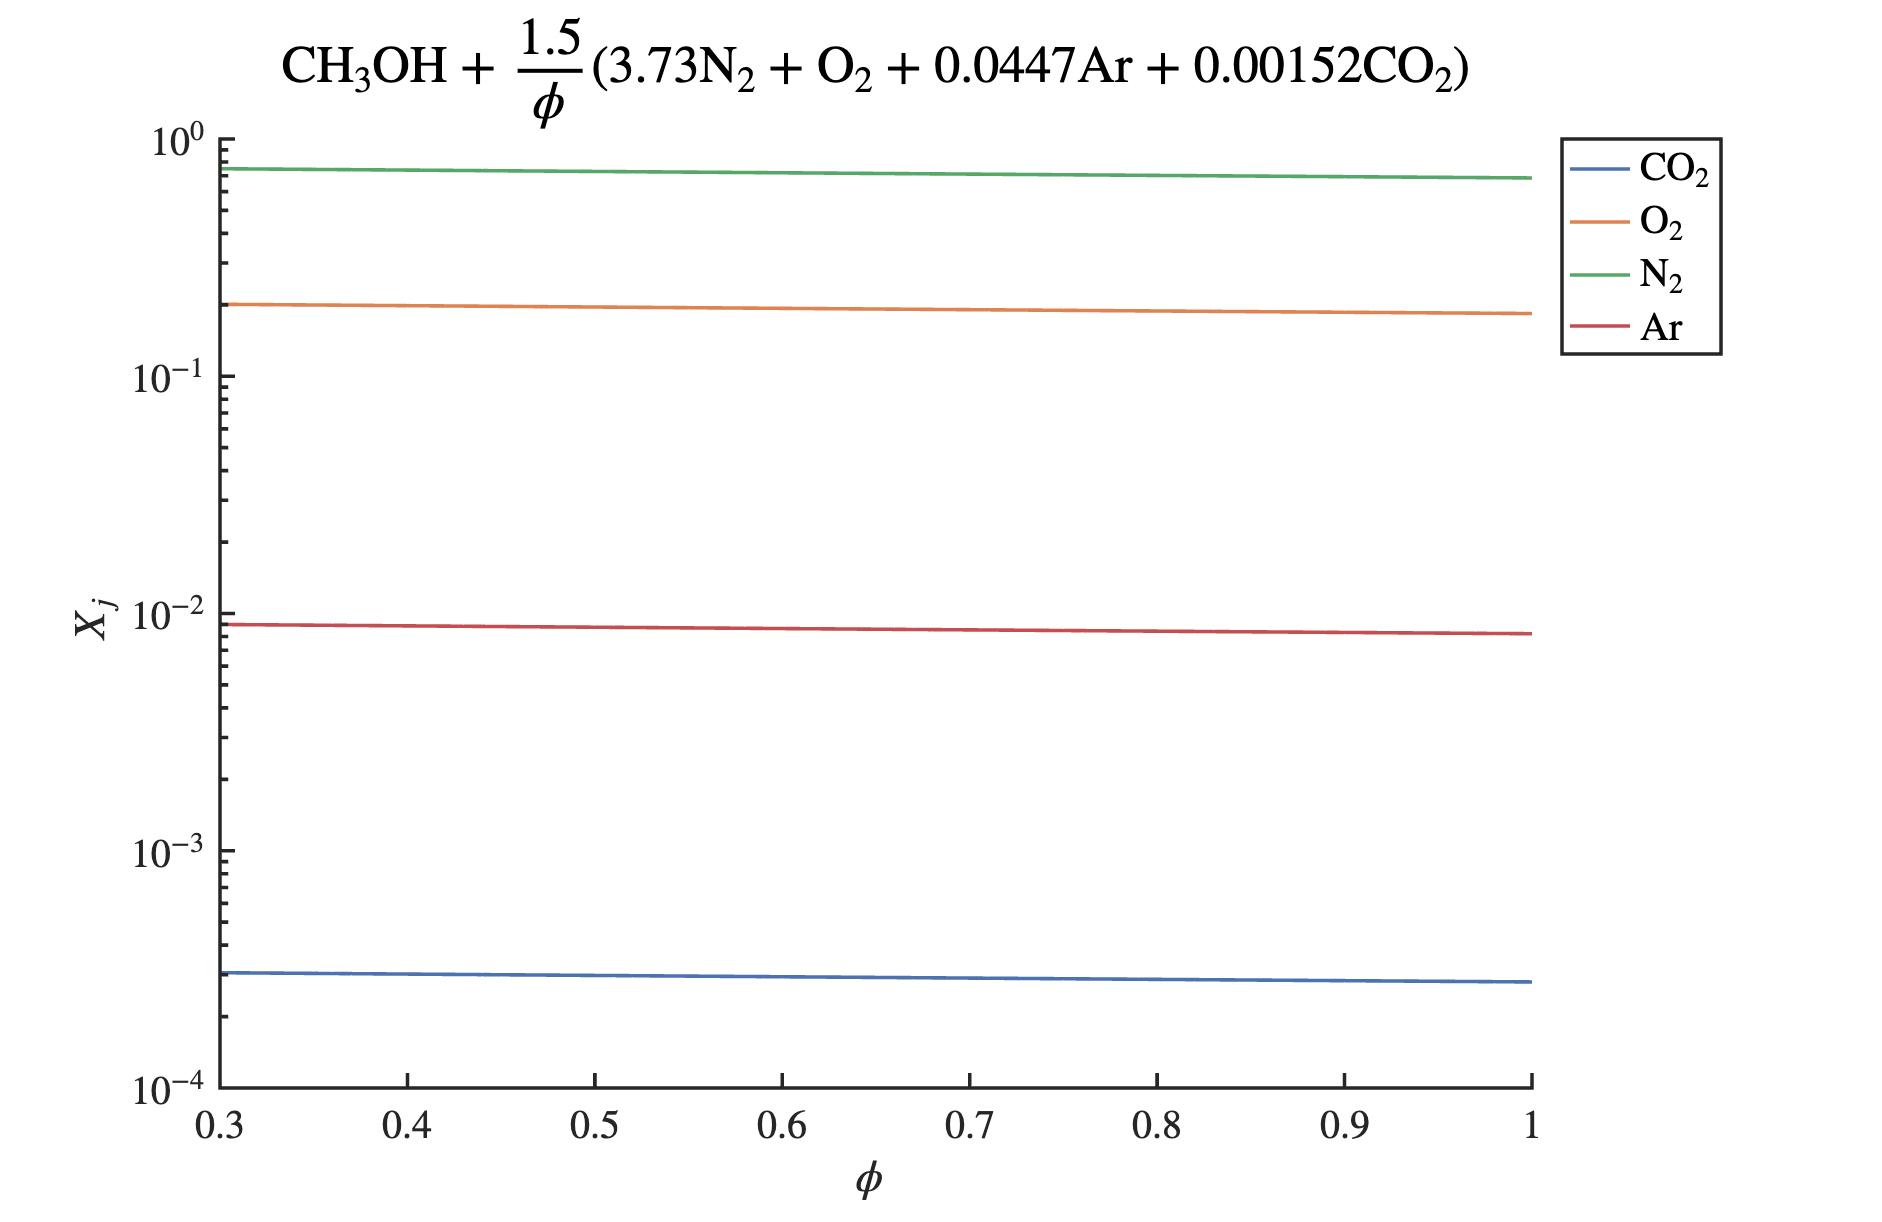

plotComposition(mixArray1(1), mixArray1, 'equivalenceRatio', 'Xi', 'mintol', 1e-4);

## 2. The mole fractions of the product mixture

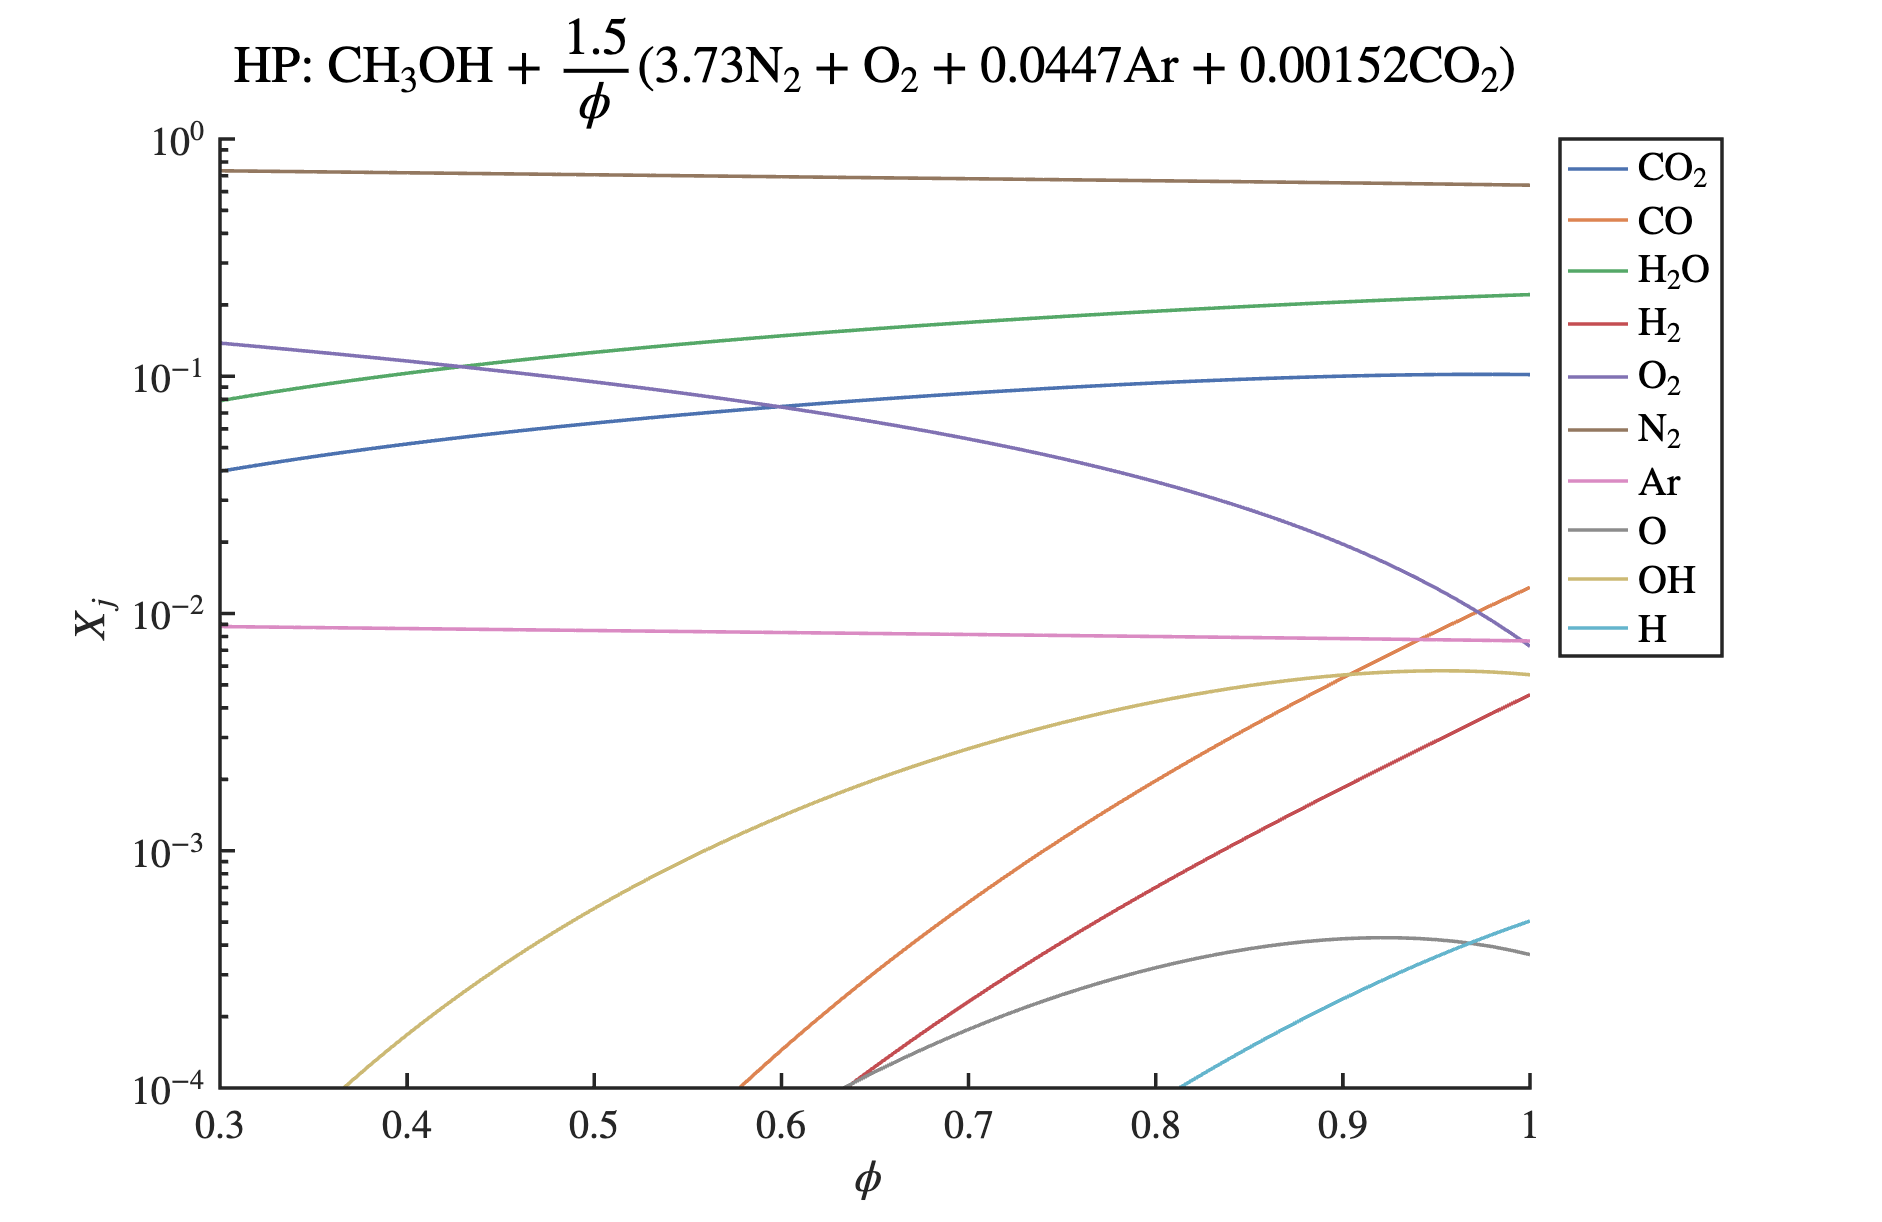

plotComposition(mixArray2(1), mixArray2, 'equivalenceRatio', 'Xi', 'mintol', 1e-4);

## 3. The adiabatic flame temperature

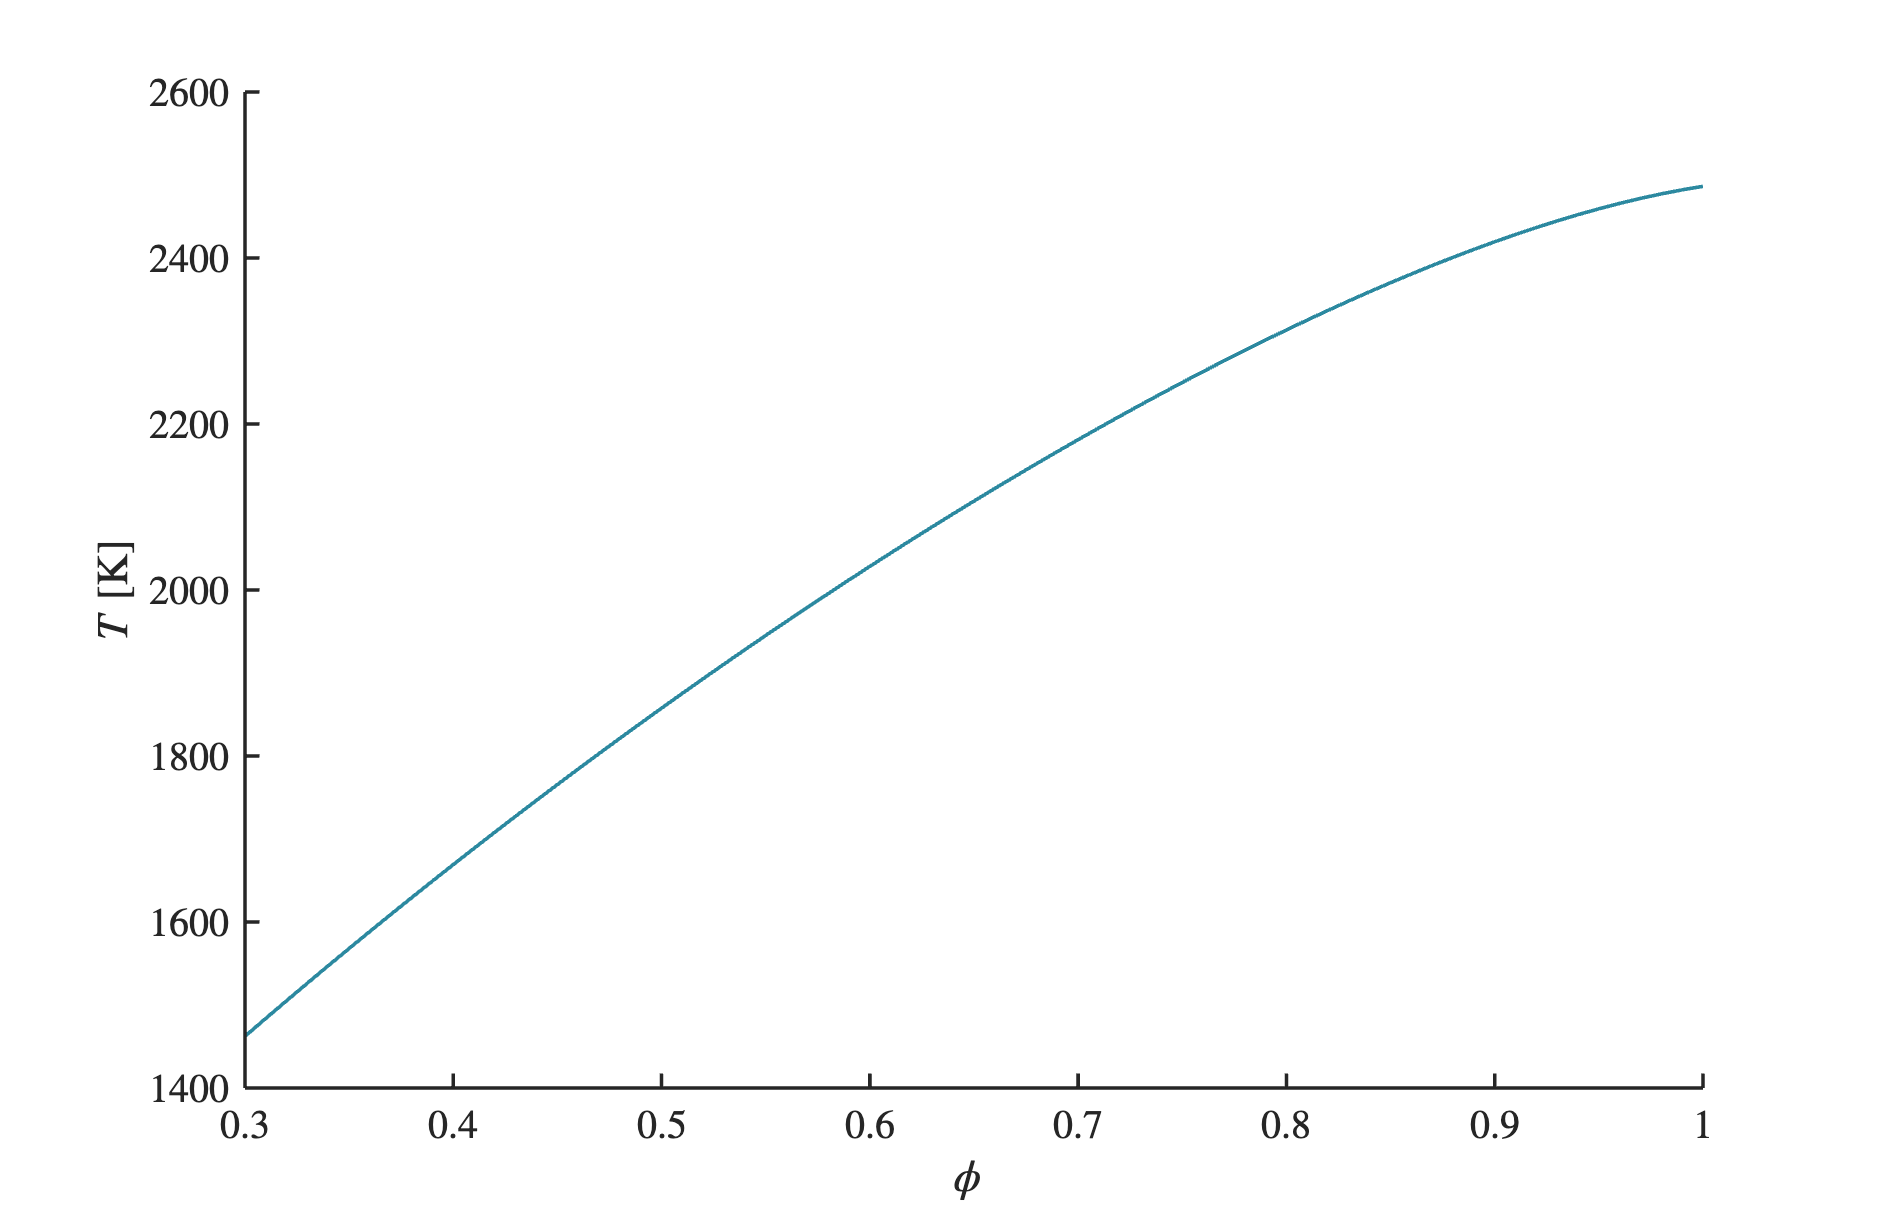

plotFigure('equivalenceRatio', mixArray2, 'T', mixArray2);

## 4. The molar fraction of nitric oxide at the exit of the combustion chamber, XNO

Compute NO using Zeldovich mechanism

% Universal gas constant [J/mol K]
R0 = Constants.R0;

% Pressure [Pa]
p = Units.convert(pR, 'bar', 'Pa');

% Temperature of the products [K]
T = [mixArray2.T];

% Concentration of the mixture == C_M = n_total / v = p / (R0 * T) 
C_M = (p ./ (R0 * T));

% Molar fraction of the products [-]
molarFractions = cell2vector(mixArray2, 'Xi');

% Get indeces N2, O
index_N2 = findIndex(system.listSpecies, 'N2');
index_O = findIndex(system.listSpecies, 'O');

% Get molar fractions of N2 and O
X_N2_eq = molarFractions(index_N2, :);
X_O_eq = molarFractions(index_O, :);

% Compute molar fraction of NO using Zeldovich mechanism
X_NO_zeld = 3.6e8 * exp(-38610 ./ T) .* C_M .* X_O_eq .* X_N2_eq .* t_r;

## 5. What is the maximum value of $\phi <1$ that allows guaranteeing a molar fraction of nitric oxide less than 50 ppm?

Compute intersection points (needs Curves Intersection - FileExchange)

% Set limit conditions (50 ppm of NO)
line_dashed_y = 50 * ones(1, length(mixArray1));

% Compute intersection point limit emissions
P = InterX([phi; X_NO_zeld * 1e6], [phi; line_dashed_y]);
phi_critical = P(1,:);
X_NO_critical = P(2,:);

% Print values
fprintf('NOx critical value emissions for an equivalence ratio = %.4f\n', phi_critical);

NOx critical value emissions for an equivalence ratio = 0.5944


## 6. Finally calculate the molar fraction of nitric oxide at the combustion chamber outlet assuming that NO is also in equilibrium

**6.1 Compute composition at adiabatic temperature and composition at constant pressure with NO**

% Set list of species
listSpecies{end+1} = 'NO';

% Define chemical system
system = ChemicalSystem(DB, listSpecies);

% Initialize mixture
mix = Mixture(system);

% Define chemical state
set(mix, {fuel}, 'fuel', 1);
set(mix, {'N2', 'O2', 'Ar', 'CO2'}, 'oxidizer', [78.084, 20.9476, 0.9365, 0.0319] / 20.9476);

% Define properties
mixArray1 = setProperties(mix, 'temperature', TR, 'pressure', pR, 'equivalenceRatio', phi);

% Create shallow copy for products
mixArray2 = mixArray1.copy();

% Solve problem
solver.solveArray(mixArray2);


Elapsed time is 0.19310 seconds



% Molar fraction of the products [-]
molarFractions = cell2vector(mixArray2, 'Xi');

% Get indeces N2, O
index_NO = findIndex(system.listSpecies, 'NO');

% Get molar fractions of NO
X_NO_eq = molarFractions(index_NO, :);

**6.2 Compute intersection point limit validity of Zeldovich mechanism. Obtaining the chemical characteristic time of NO**

% Estimate chemical characteristic time of NO
k1 = 1.8e8 * exp(-38610 ./ T); % [m3 / (mol s)]
dX_NOdt = 2 * k1 .* C_M .* X_N2_eq .* X_O_eq; % [1 / s]
t_NO = X_NO_eq ./ dX_NOdt; % [s] or equivalently tau_c = (1 / t_r * X_NO_zeld ./ X_NO_eq).^(-1)

% Compute intersection point with residence time
P = InterX([phi; t_NO], [[phi(1), phi(end)]; [10, 10] * 1e-3]);
phi_tau_eq = P(1,:);
tau_eq = P(2,:);

% Print critical value
fprintf('Chamber outlet at equilibrium for an equivalence ratio = %.4f\n', phi_tau_eq);

Chamber outlet at equilibrium for an equivalence ratio = 0.8846


**Plot results**

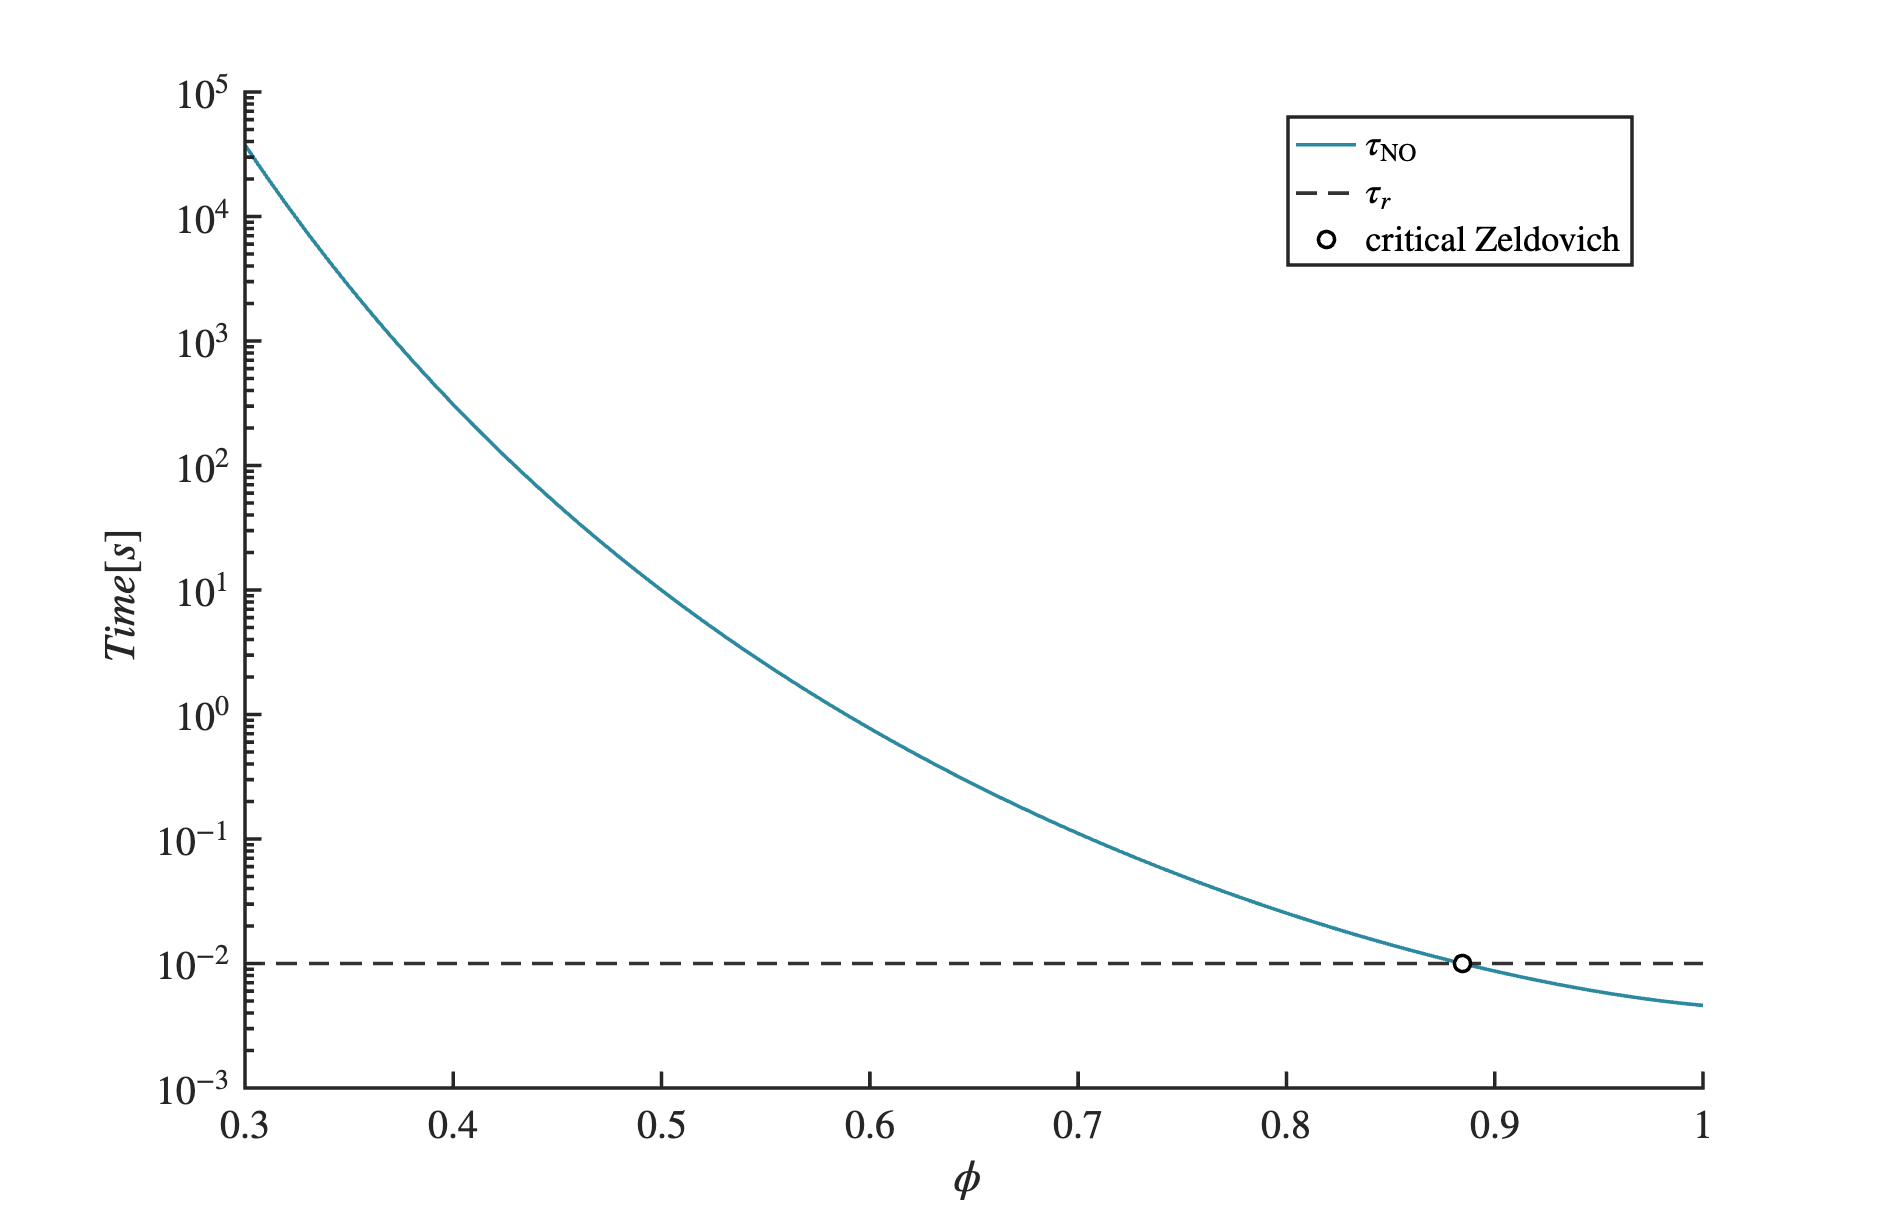

% Configure figure
plotConfig = PlotConfig();
plotConfig.yscale = 'log';
ax = setFigure(plotConfig);

% Plot results
ax = plotFigure('phi', phi, 'Time [s]', t_NO, 'ax', ax);
ax = plotFigure('phi', ax.XLim, 'Time [s]', [10, 10] * 1e-3, 'linestyle', '--', 'ax', ax, 'color', [0.2, 0.2, 0.2]);
plot(ax, phi_tau_eq, tau_eq, 'o', 'LineWidth', plotConfig.linewidth, 'MarkerFaceColor', 'auto', 'MarkerEdgeColor', 'black', 'MarkerSize', 8);
% Set legends
legendLabels = {'$\tau_{\rm NO}$', '$\tau_r$', 'critical Zeldovich'};
setLegends(ax, legendLabels);

**6.3 Compute intersection point limit validity of Zeldovich mechanism. Equilibrium achieved in the chamber.**

P = InterX([phi; X_NO_zeld * 1e6], [phi; X_NO_eq * 1e6]);
phi_zeld_eq = P(1,:);
X_NO_zeld_eq = P(2,:);

% Print critical value
fprintf('Chamber outlet at equilibrium for an equivalence ratio = %.4f\n', phi_zeld_eq);

Chamber outlet at equilibrium for an equivalence ratio = 0.8845


**Plot results**

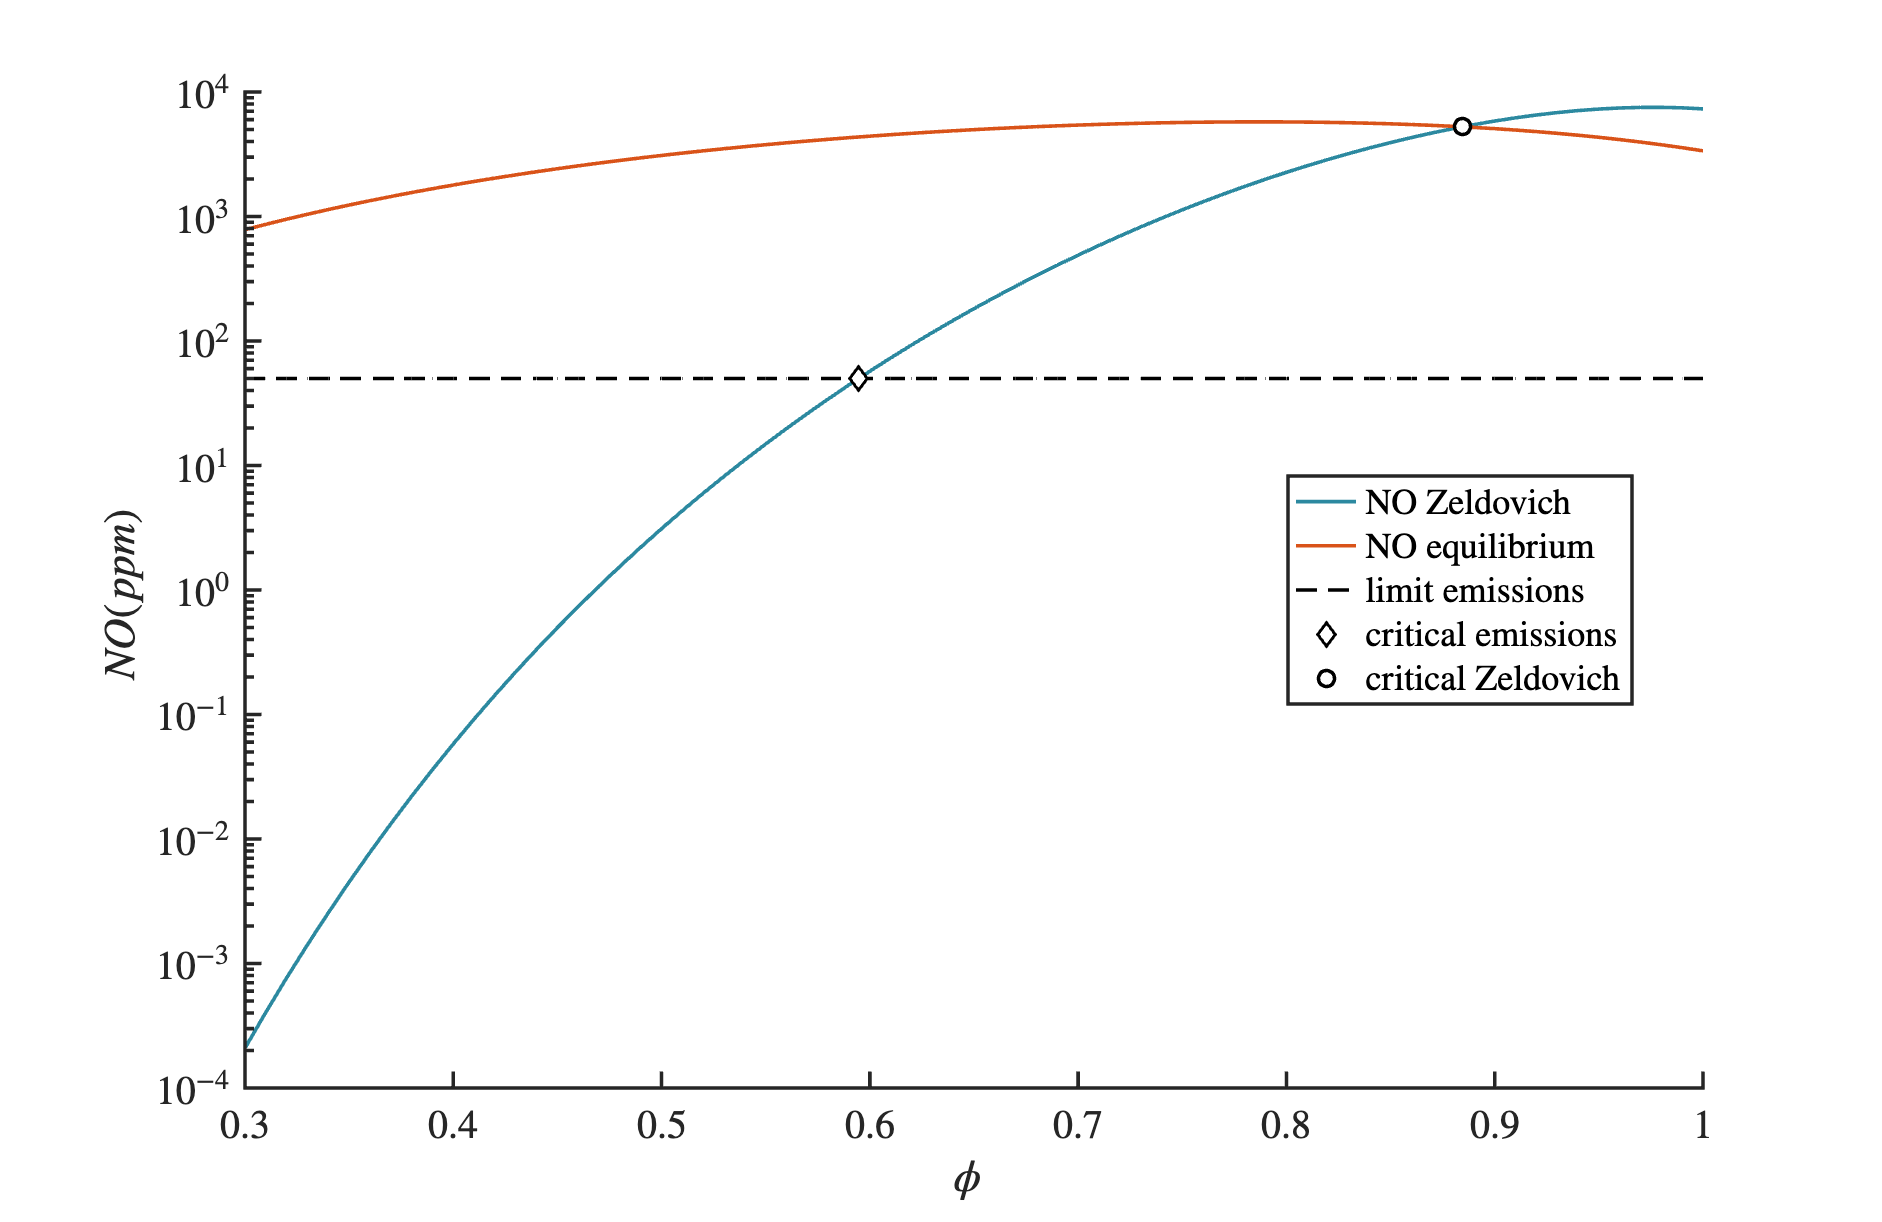

% Plot ppm of NO obtained with the mechanism of Zeldovich and considering chemical equilbrium
ax = plotFigure('phi', phi, 'NO (ppm)', X_NO_zeld * 1e6);
ax = plotFigure('phi', phi, 'NO (ppm)', X_NO_eq * 1e6, 'color', 'auto', 'ax', ax);

% Plot critical value and limit line
plot(ax, phi, line_dashed_y, '--k', 'LineWidth', plotConfig.linewidth);
plot(ax, phi_critical, X_NO_critical, 'd', 'LineWidth', plotConfig.linewidth, ...
    'MarkerFaceColor', 'auto', 'MarkerEdgeColor', 'black', 'MarkerSize', 8);
plot(ax, phi_zeld_eq, X_NO_zeld_eq, 'o', 'LineWidth', plotConfig.linewidth, ...
    'MarkerFaceColor', 'auto', 'MarkerEdgeColor', 'black', 'MarkerSize', 8);
set(ax,'yscale','log');

% Set legends
legendLabels = {'NO Zeldovich', 'NO equilibrium', 'limit emissions', 'critical emissions', 'critical Zeldovich'};
setLegends(ax, legendLabels);